Initialization

clc;clear;close all

safety_value = 1.3;

% TODO: are these finalized?
m = 10700; % [kg]
W = m * 9.81 * safety_value; % [N]
taper_ratio = 0.88;
c1 = 2.2; % [m] Base chord length
c2 = c1 * taper_ratio; % [m] Tip chord length
c_average = (c1 + c2) / 2;
b = 20; % [m] Wing span (both wings)
S_w = (c1 + c2)/2 * b; % [m^2]
e = 0.98; % [-]
AR = b^2 / S_w; % [-]
landing_gear_height = 1.5; % [m]

L = b / 2; % [m]

Now we calculate the lift distribution

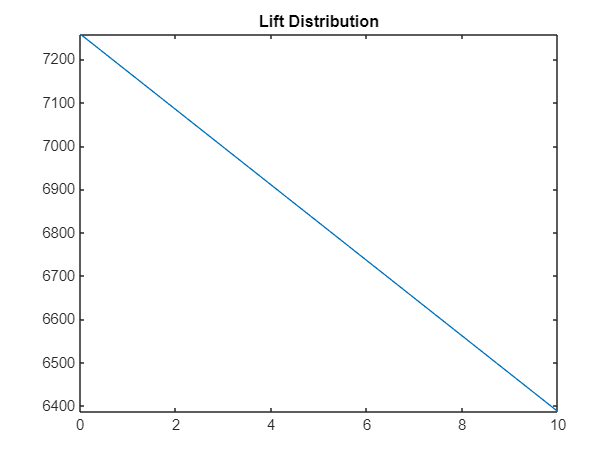

syms x
n = 20;
c = c1 - (c1-c2)*(x/L);

distributed_lift = W / S_w * c; % [N/m]

F_R = W/2;


figure
fplot(distributed_lift, [0, L])
title('Lift Distribution')

Calculating the internal shear

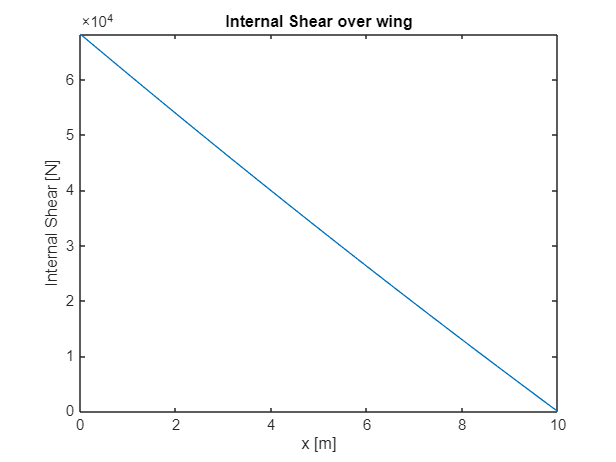

S = int(distributed_lift, x, 0, x) - F_R;
figure
fplot(-S, [0, L])
title('Internal Shear over wing')
ylabel('Internal Shear [N]')
xlabel('x [m]')

Calculating internal moment

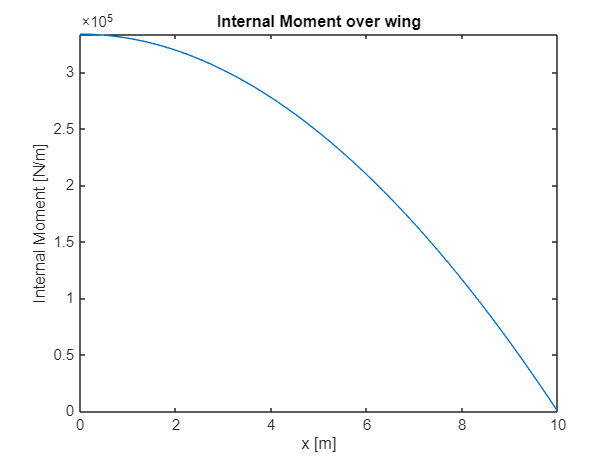

M_R = int(x * distributed_lift, x, 0, L);
M = M_R - int(x * distributed_lift, x, 0, x);
figure
fplot(M, [0, L])
title('Internal Moment over wing')
ylabel('Internal Moment [N/m]')
xlabel('x [m]')


% The moment function is a 3rd order polynomial
assert(polynomialDegree(M) == 3)

Defining spar properties and calculating bended wing shape

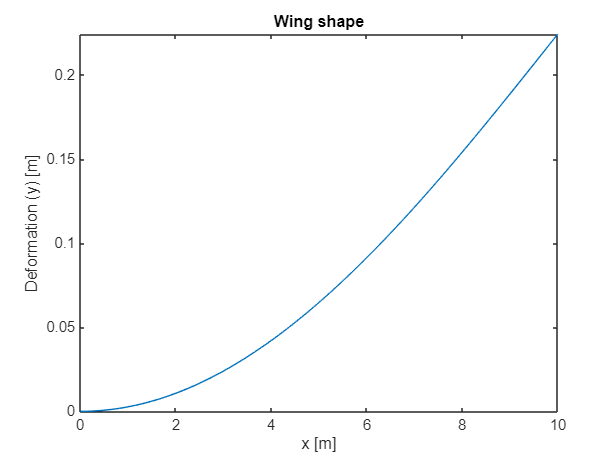

spar.t = 10e-3; % [m]
spar.w = 300e-3; % [m]
spar.h = 400e-3; % [m]
spar.I = spar.t*spar.h^3 / 12 + spar.w*spar.t*spar.h^2 / 2;
spar.E = 210e9; % [Pa]

d2ydx2 = M / (spar.E*spar.I);
dydx = int(d2ydx2, x);
y = int(dydx, x);
figure
fplot(y, [0, L])
title('Wing shape')
ylabel('Deformation (y) [m]')
xlabel('x [m]')

Calculating maximum wing stress.

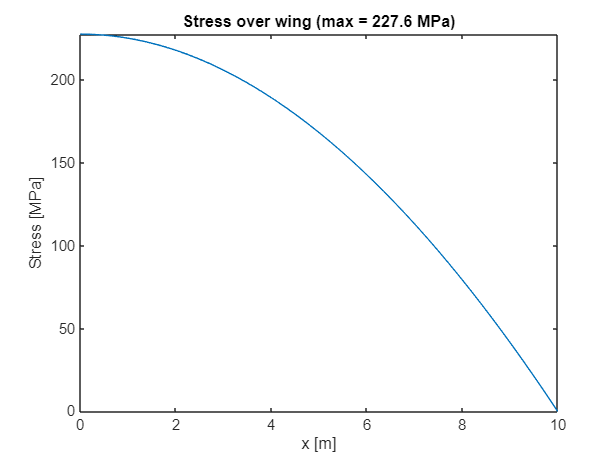

stress = M * spar.h/2 / spar.I;
figure
fplot(stress/1e6, [0, L])
title(['Stress over wing (max = ', num2str(double(subs(stress, x, 0))/1e6, 4), ' MPa)'])
ylabel('Stress [MPa]')
xlabel('x [m]')

Calculating the strain at the top of the wing. This is done so that buckling calculations can be done for the top and bottom of the wing.

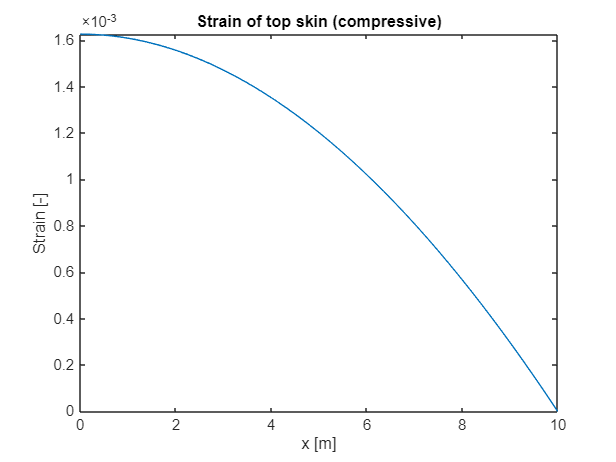

strain = d2ydx2 * 300e-3;
figure
fplot(strain, [0, L])
title('Strain of top skin (compressive)')
ylabel('Strain [-]')
xlabel('x [m]')

Now we go on to find out what should be the spacing of the ribs. We assume that the skin with stringers rotates along the plane of the skin. Because of this we can also assume that most of the bending stiffness comes from the stringers. And the skin with stringers can rotate at it's connection point with the ribs.

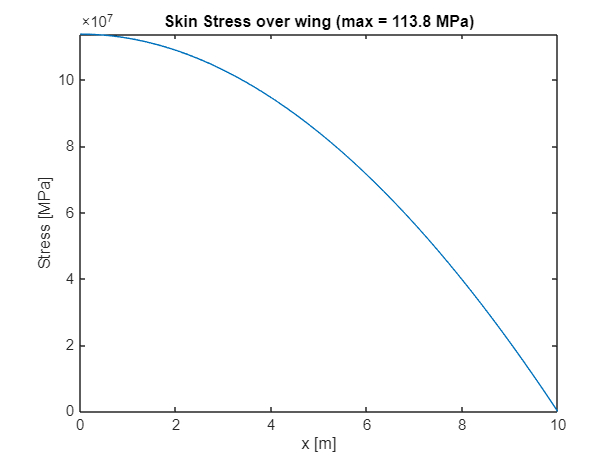

stringers.t = 4e-3; % [m]
stringers.h = 50e-3; % [m]
stringers.w = 50e-3; % [m]
stringers.I = stringers.t * stringers.h^3 / 3; % [m^4]
E_aluminium = 70e9; % [Pa]
stringers_spacing = 0.3; % [m] Distance between stringers
skin_thickness = 2e-3;
stringer_section_stress = E_aluminium * strain;
stringer_section_area = (stringers.h+stringers.w)*stringers.t + skin_thickness*stringers_spacing; % [m^2] per stringer
stringer_section_force = stringer_section_stress * stringer_section_area;

figure
fplot(stringer_section_stress, [0, L])
title(['Skin Stress over wing (max = ', num2str(double(subs(stringer_section_stress, x, 0))/1e6, 4), ' MPa)'])
ylabel('Stress [MPa]')
xlabel('x [m]')

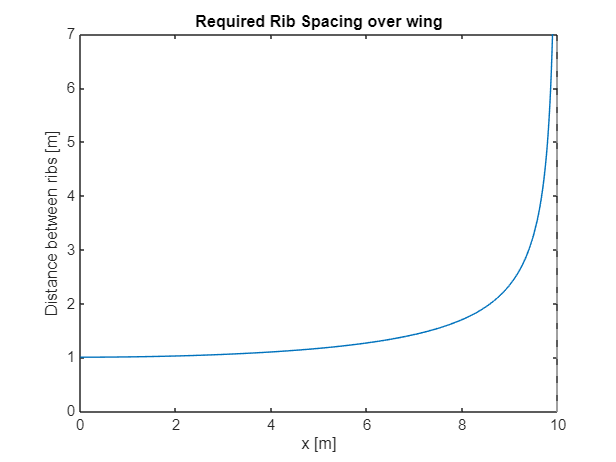

rib_spacing = sqrt(pi^2 * E_aluminium * stringers.I / stringer_section_force);

figure
fplot(rib_spacing, [0, L])
title('Required Rib Spacing over wing')
ylabel('Distance between ribs [m]')
xlabel('x [m]')
axis([0 10 0 7])

Judging by this the distance between ribs cannot be larger than 1 meter. Since this value does not significantly go up it makes sense to make the rib spacing constant at 1 meter.